% This code is responsible for identifying provided shapes and determining
% whether the shape and colour is desired by the customer
% By Kevinly Santoso
% Last Updated: 07/08/2019

%{

Source:
    https://au.mathworks.com/help/vision/ug/local-feature-detection-and-extraction.html
    https://au.mathworks.com/help/vision/ref/detectfastfeatures.html
    https://au.mathworks.com/help/vision/ref/detectharrisfeatures.html
    https://au.mathworks.com/help/vision/ref/matchfeatures.html
    https://au.mathworks.com/help/vision/examples/object-detection-in-a-cluttered-scene-using-point-feature-matching.html
    https://au.mathworks.com/matlabcentral/fileexchange/34626-object-matching
    https://au.mathworks.com/matlabcentral/answers/114176-matching-signs-using-surf

Other feature detection methods:
    https://au.mathworks.com/help/vision/ref/detectmineigenfeatures.html
    https://au.mathworks.com/help/vision/ref/detectorbfeatures.html
    https://au.mathworks.com/help/vision/ref/detectmserfeatures.html
    https://au.mathworks.com/help/vision/ref/detectbriskfeatures.html

%}

## Identify the colour group the given block belongs to

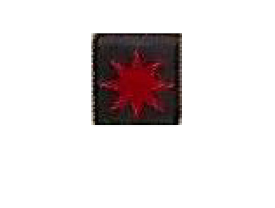

Red = 1;
Green = 2;
Blue = 3;
Yellow = 4;

myShp = imread('All_Shapes\Red_6star.PNG');
myPattern = imread('Assignment_2_Test_Pics\Test_Pattern.PNG');
myPatternGray = rgb2gray(myPattern);
figure(); imshow(myShp);

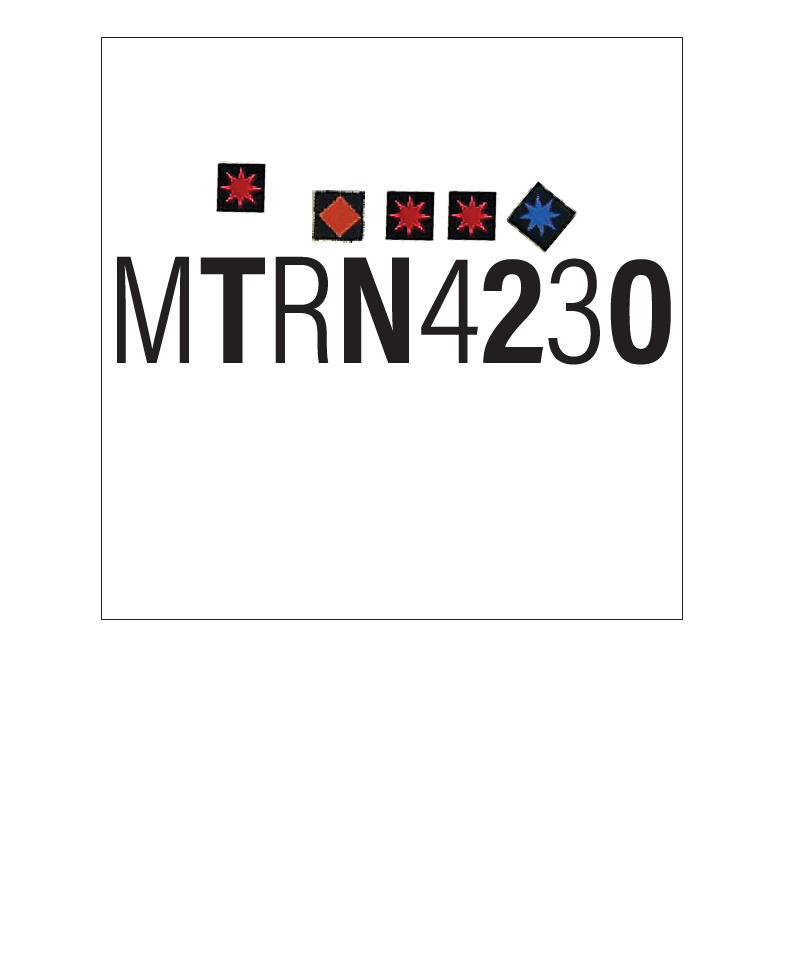

figure(); imshow(myPattern);


% filter out the shape using all the colour masks
[myRedShpBW,myRedShp] = createRedMask(myShp);
[myGreenShpBW,myGreenShp] = createGreenMask(myShp);
[myBlueShpBW,myBlueShp] = createBlueMask(myShp);
[myYellowShpBW,myYellowShp] = createYellowMask(myShp);

% remove any white noise from all the masks
myRedShpBW = bwareaopen(myRedShpBW,60); 
myGreenShpBW = bwareaopen(myGreenShpBW,60); 
myBlueShpBW = bwareaopen(myBlueShpBW,60); 
myYellowShpBW = bwareaopen(myYellowShpBW,60); 

% determine if the colour is red, green, blue or yellow
redExist = find(myRedShpBW);
greenExist = find(myGreenShpBW);
blueExist = find(myBlueShpBW);
yellowExist = find(myYellowShpBW);

%{
% create a border 
myRedShp = createBorder(myRedShp);
myGreenShp = createBorder(myGreenShp);
myBlueShp = createBorder(myBlueShp);
myYellowShp = createBorder(myYellowShp);
%}

## Extract features from given block

if length(redExist) > 10
    display("It's a red shape");
    blockColour = Red;
    myShpGray = rgb2gray(myRedShp);
    myFinalShp = myRedShp;
    
elseif length(greenExist) > 10
    display("It's a green shape");
    blockColour = Green;
    myShpGray = rgb2gray(myGreenShp);
    myFinalShp = myGreenShp;

elseif length(blueExist) > 10
    display("It's a blue shape");
    blockColour = Blue;
    myShpGray = rgb2gray(myBlueShp);
    myFinalShp = myBlueShp;
    
elseif length(yellowExist) > 10
    display("It's a yellow shape");
    blockColour = Yellow;
    myShpGray = rgb2gray(myYellowShp);
    myFinalShp = myYellowShp; 
end

    "It's a red shape"



## Identify the colour group the desired blocks belongs to

    "Colour exist in pattern"



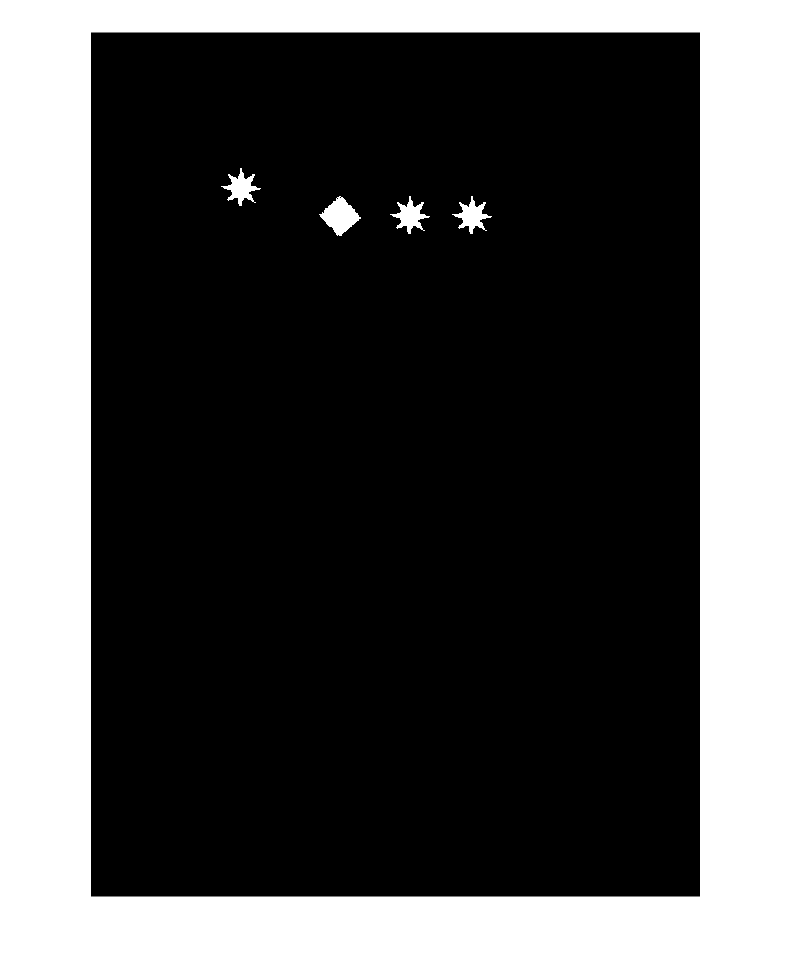

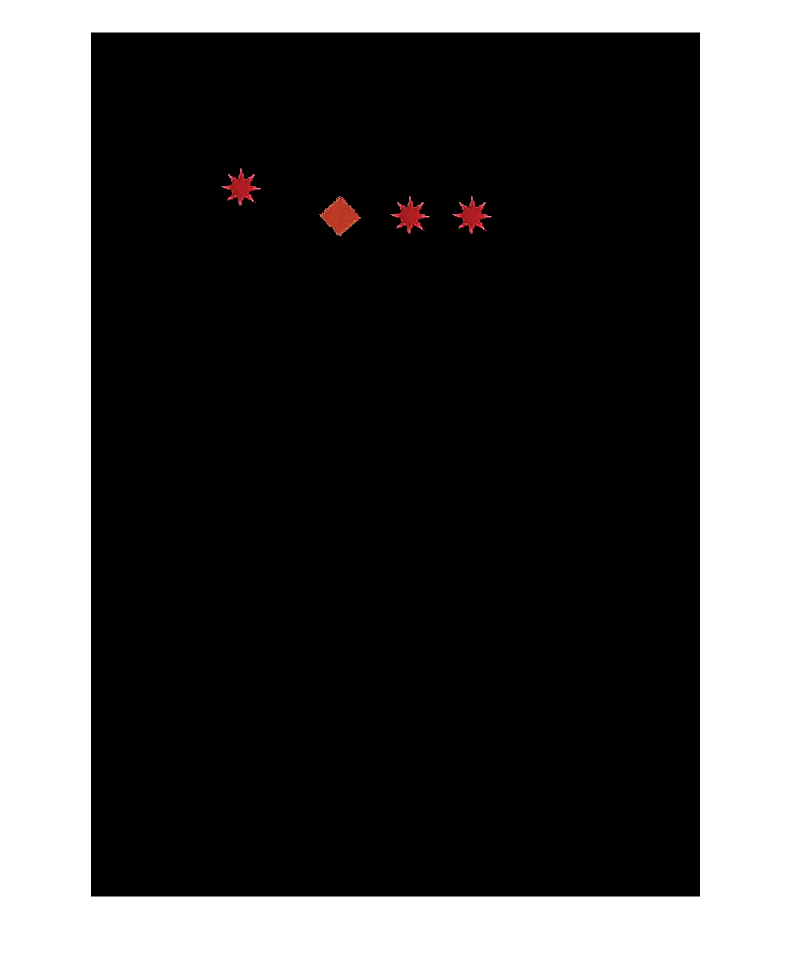

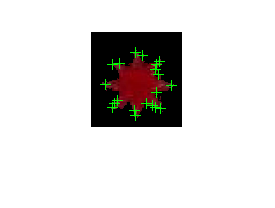

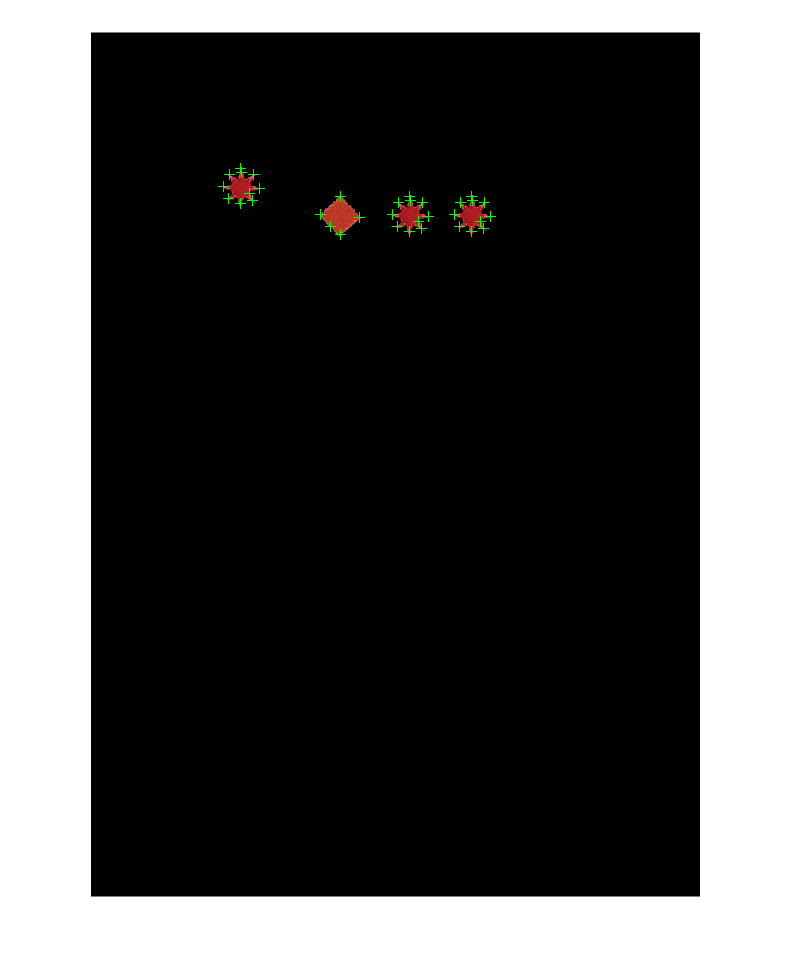

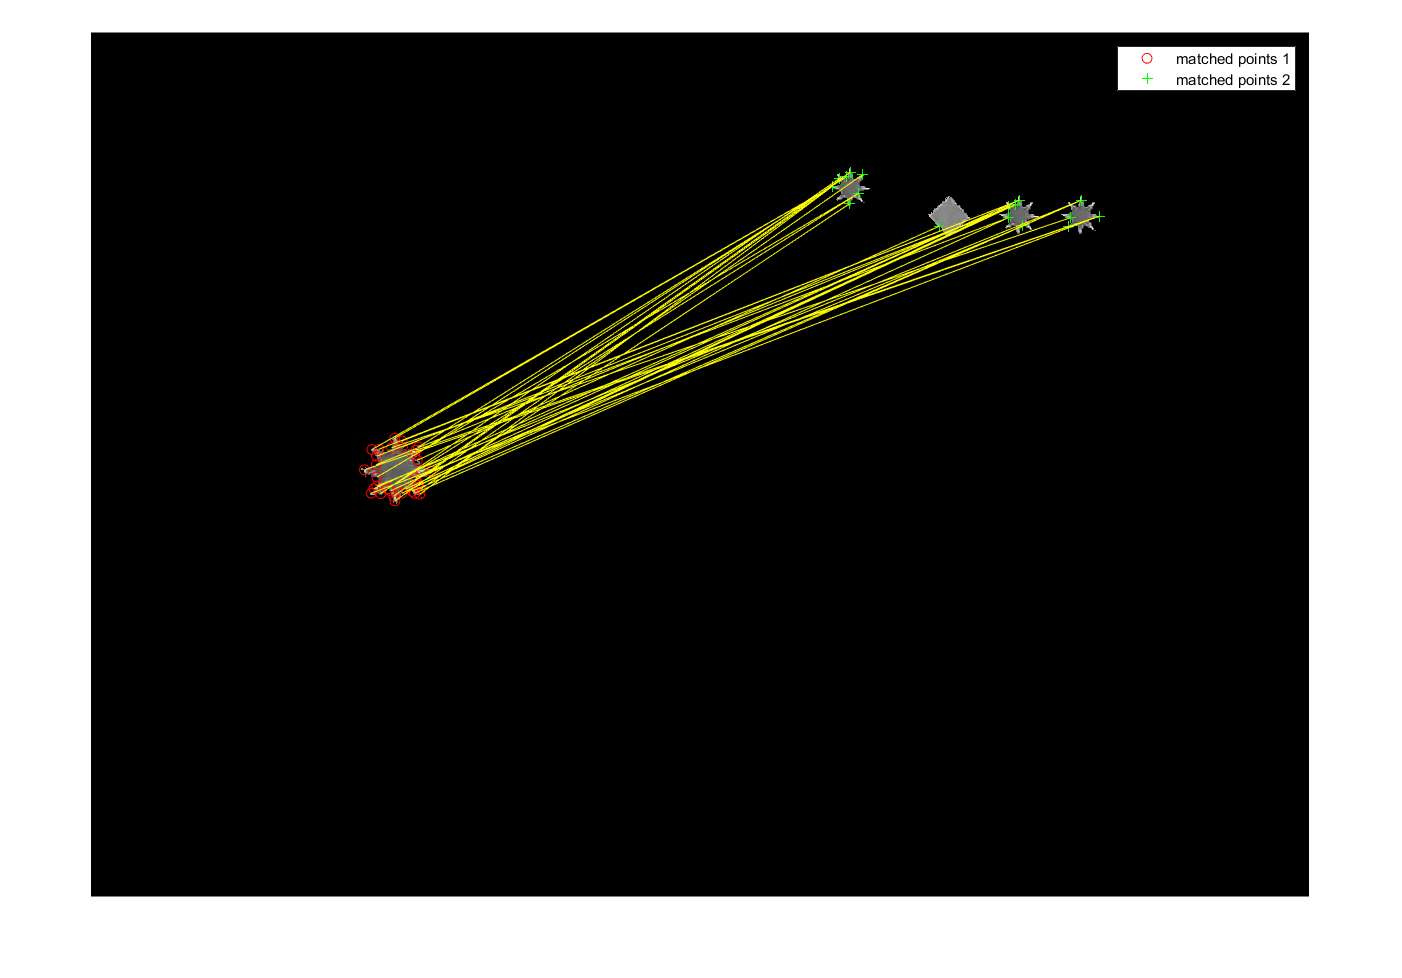

if blockColour == Red
    [ColourPatternBW,ColourPattern] = createRedPatternMask(myPattern);
elseif blockColour == Green
    [ColourPatternBW,ColourPattern] = createGreenMask(myPattern);
elseif blockColour == Blue
    [ColourPatternBW,ColourPattern] = createBlueMask(myPattern);
elseif blockColour == Yellow
    [ColourPatternBW,ColourPattern] = createYellowMask(myPattern);
end

%ColourPatternBW = bwareaopen(ColourPatternBW,60); 
%filledObjs = regionprops(ColourPatternBW, 'FilledImage');
%ColourPatternBW = filledObjs(2).FilledImage;
%ColourPattern = bsxfun(@times,myPattern,cast(ColourPatternBW,'like',myPattern));
colourExist = find(ColourPatternBW);

% This happens if any of the colours on the pattern matches the colour of the block given
if length(colourExist) > 10
    display("Colour exist in pattern");
    figure(); imshow(ColourPatternBW);
    figure();
    imshow(ColourPattern);
    
    %% extract feature from the block
    figure();
    imshow(myFinalShp); 
    hold on;
    blockPts = detectHarrisFeatures(myShpGray);
    plot(blockPts.selectStrongest(20)); 
    hold off;
    
    %% extract feature from the Pattern
    figure();
    imshow(ColourPattern);
    myPatternGray = rgb2gray(ColourPattern);
    hold on;
    patternPts = detectHarrisFeatures(myPatternGray);
    plot(patternPts.selectStrongest(35)); 
    hold off;
    
    %% Match the shape between the block and pattern
    [blockFtrs,blockValidPts] = extractFeatures(myShpGray,blockPts, 'Method', 'KAZE');
    %
    [patternFtrs,patternValidPts] = extractFeatures(myPatternGray,patternPts, 'Method', 'KAZE');
    indexPairs = matchFeatures(blockFtrs, patternFtrs, 'MaxRatio', 1,'MatchThreshold', 100);
    % 
    matchedBlockPoints = blockValidPts(indexPairs(:,1),:);
    matchedPatternPoints = patternValidPts(indexPairs(:,2),:);
    
    figure(); 
    showMatchedFeatures(myShpGray,myPatternGray,matchedBlockPoints,matchedPatternPoints, 'montage');
    legend('matched points 1','matched points 2');
    
    

else
    display("Colour doesn't exist in pattern");
end

## Feature Matching

## Other functions

function Img = createBorder(Img)
thickness = 15;
Img(1:1+thickness, :, :) = 255;
Img(end-thickness:end, :, :) = 255;
Img(:, 1:1+thickness, :) = 255;
Img(:, end-thickness:end, :) = 255;
end